# Course Project (MSE 422): Cathode Degradation Analysis

Source: E. Fensterle *et al.*, “Spatially Resolved Electrochemical Characterization of a PEM Fuel Cell Stack During Durability Testing,” *International Journal of Hydrogen Energy*, vol. 250, Art. no. 156060, July 2026, doi: 10.1016/j.ijhydene.2026.156060.

## From the research article

### 1. Lab setup

The study targets the durability of proton exchange membrane fuel cells (PEMFC) for heavy-duty applications, and the need to identify and understand the aging mechanisms.The investigation on the membrane electrode assembly (MEA) is particularly important, since the MEA drives fuel-cell performance degradation during aging. The work focuses on spatially resolved aging effect across the active area, which is done with the CDDM (segmented current-density measurement board) and special expansion boards that transmit the current from the measurement segments to the Zahner device.

Testing condition: Coolant flow was kept constant, chosen so the inlet-to-outlet temperature difference was 10 K at the highest load point (1.8$A/cm^2$)

The test subject is the generic HyFaB stack with an active area of 280 $cm^2$ per cell and a project-specific MEA. Two builds were used: 

- a 10-cell stack for the durability test 

- an 8-cell stack for the BoL EIS sensitivity analysis.

### 2. Testing procedure

A heavy duty load cycle was applied for more than 2000 hours to the stack. At regular intervals the stack was characterized with polarization curves, sensitivity tests, and electrochemical impedance spectroscopy (EIS) at cell level and spatially resolved. The full characterization sequence (after break-in, which aims to reach full cell performance) consisted of six polarization curves at different operating conditions, the partial sensitivity test, EIS at cell level and spatially resolved, and cyclic voltammetry.

Polarization curves were measured at 16 load points from 0 to 1.8 $A/cm^2$, in both descending and ascending order. The minimum current for stoichiometric operation was 0.3 $A/cm^2$ for the durability test and 0.5 $A/cm^2$ for the full sensitivity test. Sensitivity tests study the influence of operating conditions on performance, including temperature, humidity, pressure, and stoichiometry, at four different current densities.

EIS is a powerful method for separating the resistances of transport, conduction, and reaction processes, which occur at different frequencies. Both cell and spatially resolved impedance were measured galvanostatically. For the cell impedance the AC was 5% of the DC; for the spatially resolved measurements a slightly higher AC gave less noise.

### 3. Result from the research

Cell voltage decrease over time, and the largest jump is between BoL (beginning of life) curve and the curve after 300 hours (25 cycles), about half the total loss happens in the first 300 hours (63.3 $\mu V/h$). The degradation rate at 1.8 $A/cm^2
$ is 15.7 $\mu V/h$ overall; excluding the reversible loss (comparing the after-air/air-start curves) it drops to 13.0 $\mu V/h$, and about 2.7 $\mu V/h$ of the loss is reversible.

Degradation impact increases with decreasing pressure, especially in the resistance of the oxygen reduction reaction (ORR). Temperature, humidity and stoichiometry variations did not show a strong influence of aging; the aging effect on sensitivity becomes evident under varying pressure. Increasing operating pressure enhances reactant availability and cell operation (as at BoL), but with a much more beneficial effect after aging: higher partial pressure improves oxygen transport to the catalyst layer, mitigating the impact of aging and supporting more uniform, robust performance. Aging effects are strongest at low pressures and elevated temperatures. Heterogeneity of the current-density distribution decreases with increasing humidity, pressure and stoichiometry, but increases with temperature. Mass-transport resistance is most strongly affected by stoichiometry, with pronounced increases in the outlet region at low stoichiometric ratios.

The active area is divided into 27 columns in the flow direction and averaged per column. Over time there is a visible shift of the current-density maximum toward the cathode inlet; the inhomogeneity increases and the maximum reaches higher values after 2300 hours. At the lowest load, local current densities at the air inlet become even lower, compensated by higher values in the middle; at higher loads there is no air-inlet effect, but an increased slope between the maximum (near the air inlet) and the middle-outlet area. Degradation therefore has a greater influence on the current-density distribution at lower temperatures (and at low stoichiometry).

The impedance spectra were interpreted through three points read off the Nyquist plot. The high-frequency resistance (HFR) is the ohmic loss: mainly the membrane (proton-transport) resistance, with smaller contributions from electronic contact resistances and electrode-related effects such as ionomer distribution and possible swelling. The low-frequency resistance (LFR) is the sum of all losses. The two arcs between the HFR, intermediate-frequency (IFR) and LFR intercepts correspond to two processes: ORR charge transfer on the cathode in the intermediate-frequency range, and mass transport in the low-frequency range. These were fitted with an equivalent circuit in which R₀ is the membrane resistance and the charge-transfer and mass-transport steps are each an R-CPE element.

Across the 2300 h test, the membrane held up well. Its resistance rose only slightly, with a clearer jump after 1150 hours, consistent with chemical aging of the membrane (radical attack that lowers proton conductivity) and possibly a small rise in interfacial contact resistance (e.g. between the gas-diffusion layer and the bipolar plate). Because this increase was small, the ohmic term changed little overall, and aging produced only minor effects in the average cell-level impedance.

The dominant degradation was on the cathode. The ORR charge-transfer resistance increased over time, driven by catalyst aging (Pt particle growth, dissolution and agglomeration, and carbon-support corrosion) that reduces the electrochemically active surface area (ECSA), with the loss concentrated in the cathode outlet region. The mass-transport resistance, which would normally grow as gas-diffusion paths become blocked (liquid-water accumulation, loss of GDL hydrophobicity, pore-structure changes, carbon-support corrosion), instead stayed roughly constant; the authors attribute this to the test avoiding high potentials and possibly being too short to trigger those mechanisms. In short, catalyst degradation mainly affected the ECSA and therefore the charge-transfer resistance, while the ohmic/membrane resistance remained largely unaffected.

## For this project

### 1. Aim of this project

<Plan: redo some analysis on the datasets on degradation effects, use the timestamps as the main reference for time, the aim is to build a regression model that can estimate the degradation effect, and testing out with optimal controller MPC, if time permits> 

### 2. Methodologies

### 3. Analysis

clear; clc; close all
here = "C:\Users\dangs\Desktop\project\fuel_cell_project\Cathode Degradation of PEMFC";
if isempty(here), here = pwd; end
dataDir = fullfile(here, 'data');
outDir  = fullfile(here, 'results');
if ~exist(outDir, 'dir'), mkdir(outDir); end

#### 1. Visualization of the degradation function

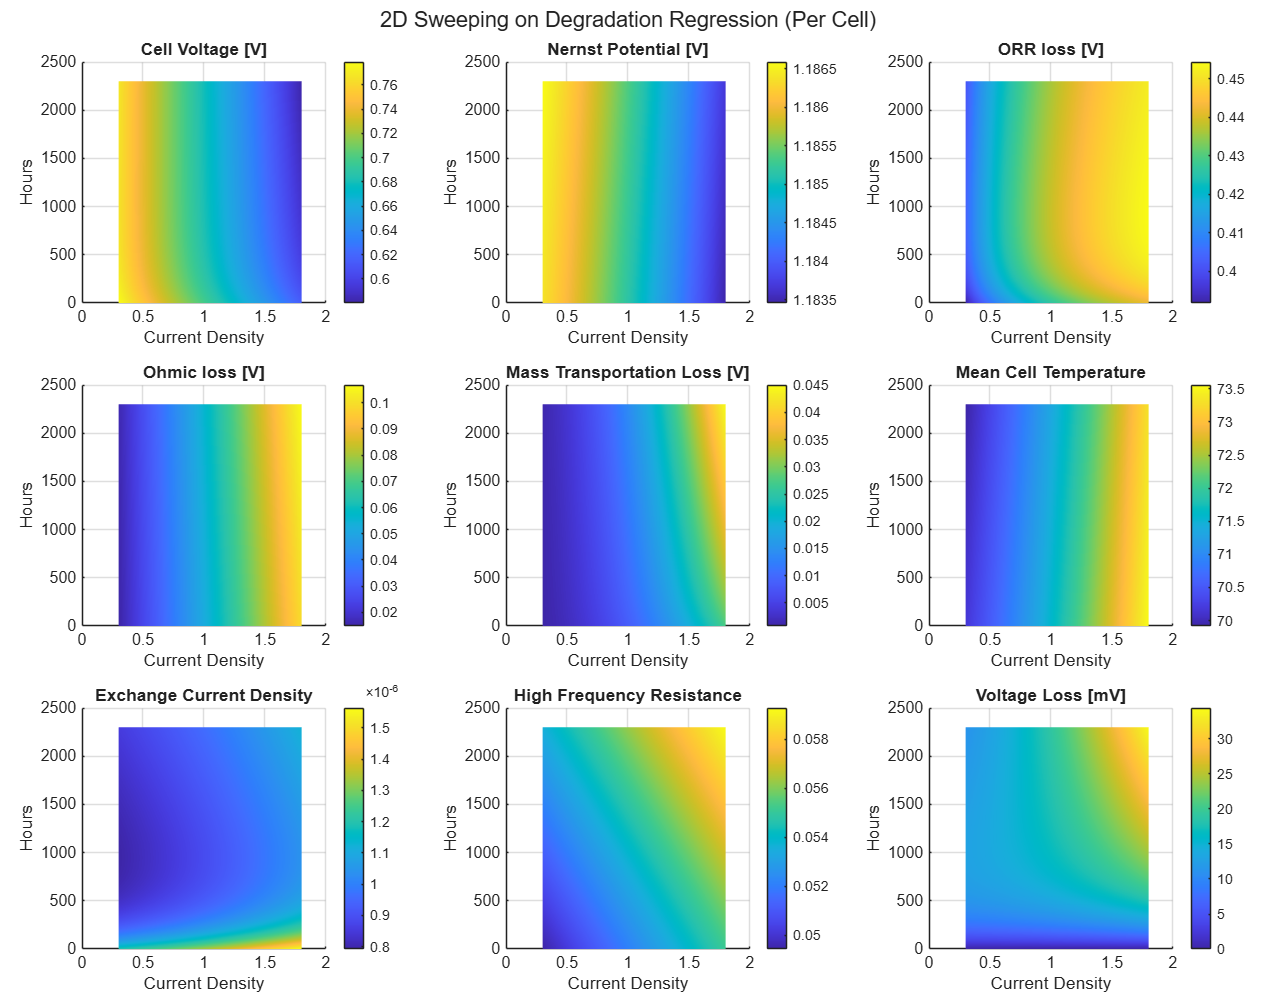

% Testing the degradation function on  default option
num_samples = 250;
current_density = linspace(0.3, 1.8, num_samples);
hours = linspace(0, 2300, num_samples);

% Create 2D grid of inputs
[J, H] = meshgrid(current_density, hours);

% Fields to plot (excluding 'params')
fields = {'U', 'E', 'eta_act', 'eta_ohm', 'eta_mt', 'T_cell', 'j0', 'HFR', 'dU_aging_mV'};
decoded_field = {'Cell Voltage [V]', 'Nernst Potential [V]', 'ORR loss [V]', 'Ohmic loss [V]', ...
                 'Mass Transportation Loss [V]', 'Mean Cell Temperature', 'Exchange Current Density', ...
                 'High Frequency Resistance', 'Voltage Loss [mV]'};
% Preallocate a struct of 2D matrices
results = struct();
for f = 1:numel(fields)
    results.(fields{f}) = zeros(num_samples, num_samples);
end

% Evaluate function across the 50x50 grid
for i = 1:num_samples
    for k = 1:num_samples
        out = degradation_func(J(i,k), H(i,k));
        for f = 1:numel(fields)
            results.(fields{f})(i,k) = out.(fields{f});
        end
    end
end

% Plot 3x3 grid
figure('Name', 'Degradation Properties (2D Sweep)');
fig = figure('Position', [100, 100, 1100, 900]); % [left, bottom, width, height]
tiledlayout(3, 3, 'Padding', 'compact');
sgtitle('2D Sweeping on Degradation Regression (Per Cell)')

for f = 1:numel(fields)
    nexttile;
    surf(J, H, results.(fields{f}), 'EdgeColor', 'none');
    view(2); % Top-down 2D heatmap view (remove this line for 3D surfaces)
    colorbar;
    title(decoded_field{f}, 'Interpreter', 'none');
    xlabel('Current Density');
    ylabel('Hours');
end

#### 2. Visualization of the fuel cell stack

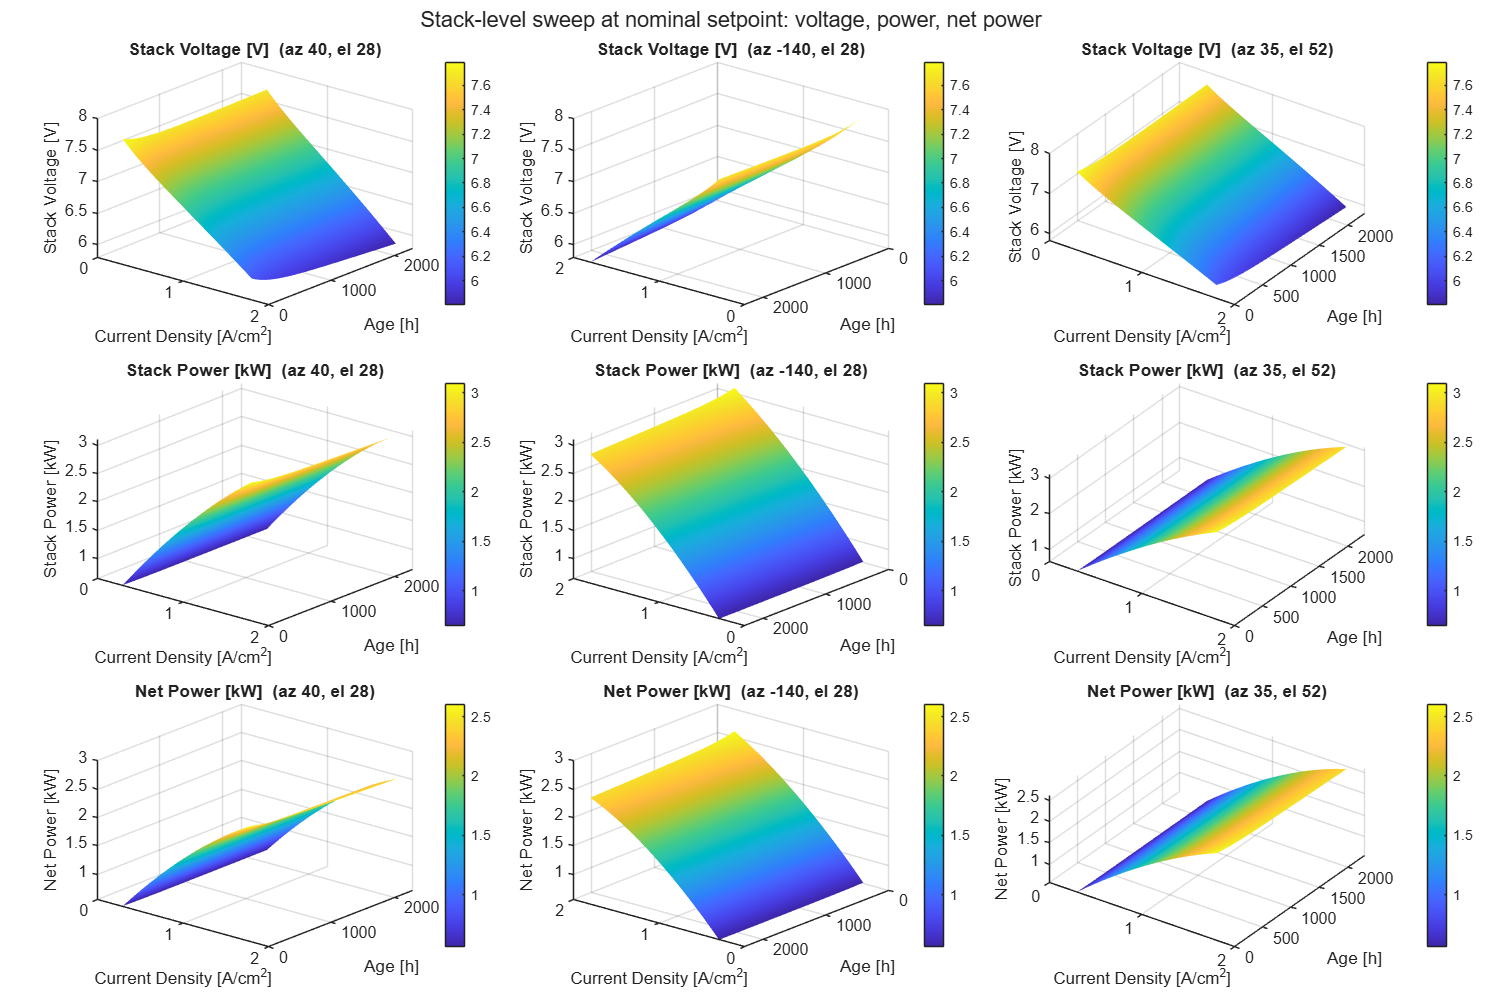

%% Constants (stack + balance of plant), from optimize_operating_point.m
P.R = 8.314; P.F = 96485; P.P0 = 101.325; % J/mol/K, C/mol, kPa
P.N = 10;    P.A = 280; % cells, active area per cell (cm^2)
P.T_amb = 298.15; % K, compressor inlet
P.eta_is = 0.70; P.eta_mot = 0.90; % compressor isentropic / motor eff.
P.dp_hum = 5; % kPa, humidifier + piping drop
P.dp_coef = [0.1495 0.00164]; % stack cathode drop dp = a*Q + b*Q^2
P.F_cl = 6.0; P.dp_cl = 47.5; P.eta_pump = 0.5; % coolant flow (L/min), drop (kPa), pump eff.
P.RH_a = 0.50; P.lam_a = 1.5; P.dpa = 10; % anode RH, stoich, anode-cathode p offset

x_nom = [150, 1.7, 70, 0.35]; % nominal [p_c kPaG, lambda_c, T_in degC, RH_c]

V_stack = zeros(num_samples); % V
P_stack = zeros(num_samples); % kW
P_net   = zeros(num_samples); % kW

for i = 1:num_samples
    for k = 1:num_samples
        s = fc_stack(J(i,k), H(i,k), x_nom, P);
        V_stack(i,k) = s.V_stack;
        P_stack(i,k) = s.P_stack / 1e3;
        P_net(i,k)   = s.P_net   / 1e3;
    end
end

views   = [40 28; -140 28; 35 52]; % [azimuth elevation]
metrics = {V_stack, 'Stack Voltage [V]'; ...
    P_stack, 'Stack Power [kW]'; ...
    P_net,   'Net Power [kW]'};

fig = figure('Name', 'Stack-level sweep', 'Position', [100 100 1300 1300*1.5]);
tiledlayout(3, 3, 'Padding', 'compact', 'TileSpacing', 'compact');
for m = 1:3
    for v = 1:3
        nexttile;
        surf(J, H, metrics{m,1}, 'EdgeColor', 'none');
        view(views(v,:)); grid on; colorbar
        xlabel('Current Density [A/cm^2]'); ylabel('Age [h]'); zlabel(metrics{m,2});
        title(sprintf('%s  (az %d, el %d)', metrics{m,2}, views(v,1), views(v,2)), ...
            'Interpreter', 'none');
    end
end
sgtitle('Stack-level sweep at nominal setpoint: voltage, power, net power')
print(fig, fullfile(outDir, 'fig_stack_sweep.png'), '-dpng', '-r130');